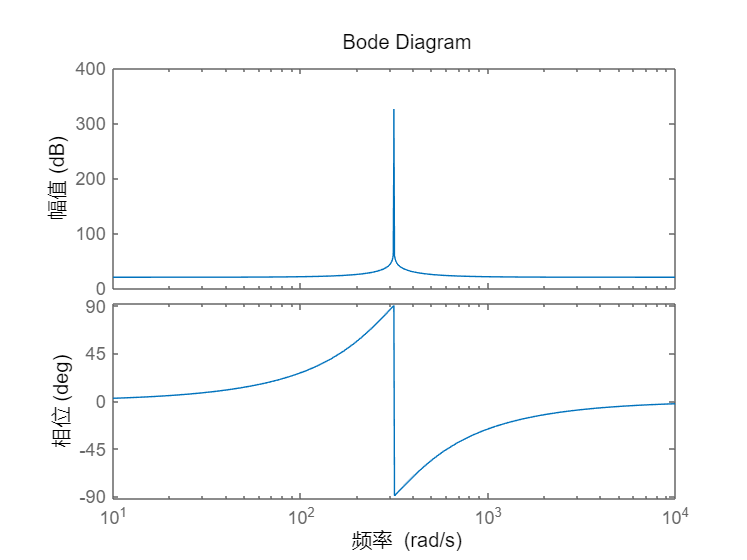

kp = 10; xi = 0.707; wn = 2*pi*50;
sys_PR = tf(kp*[1, 2*xi*wn, wn^2], [1, 0, wn^2]);
figure; bode(sys_PR)

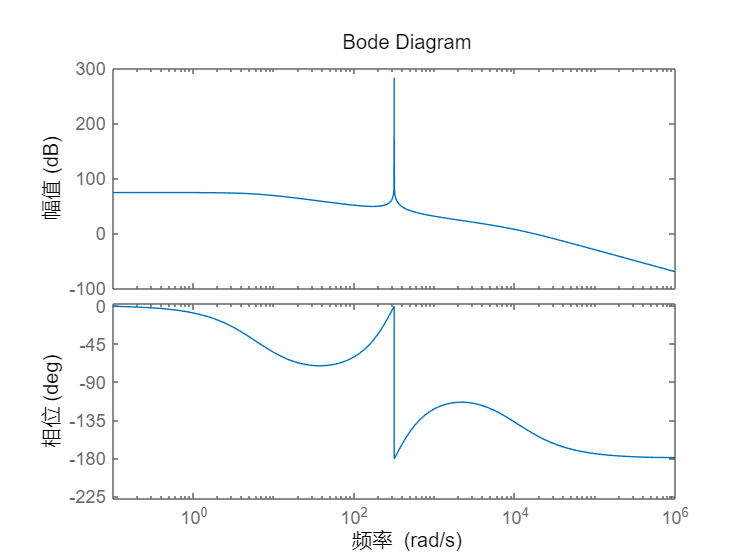

Lf = 0.1; Rf = 0.002; Td = 1/(10E3);
sys_filter = tf([1], [Lf/wn, Rf]);
sys_delay = tf([1], [Td, 1]);
figure; bode(sys_PR*sys_filter*sys_delay)